# Paint4Net: visualisation toolbox for COBRA

## Author(s):

Andrejs Kostromins, Biosystems Group, Department of Computer Systems, Latvia University of Agriculture, Liela iela 2, LV-3001 Jelgava, Latvia. 

Egils Stalidzans, Institute of Microbiology and Biotechnology, University of Latvia, Jelgavas iela 1, LV-1004, Latvia.

## Reviewer(s): 

Agris Pentjuss, Institute of Microbiology and Biotechnology, University of Latvia, Jelgavas iela 1, LV-1004, Latvia.

Almut Heinken, Luxembourg Centre for Systems Biomedicine, Universiy of Luxembourg, 6 avenue du Swing, Belvaux, L-4367, Luxembourg.

## IMPORTANT NOTE

Paint4Net uses Bioinformatics Toolbox to generate visualisation layout, however it is not supported in .mlx causing an error during function execution. Thus the functions involving visualisation were run in regular MATLAB command window and each visualisation  layout was saved as a static figure and flaced in the .mlx tutorial, while the corresponding functions were run in .mlx with visualisation feature turned off (input argument *drawMap *was set to 'false') to get outputs (without visualisation) in .mlx without crashing. Be aware of this issue when you are running the functions in .mlx. All *drawMap *input arguments are set to 'true' in .mlx. Change it to 'false' to avoid an error. 

## INTRODUCTION

A visual analysis of reconstructions and large stoichiometric models with elastic change of the visualization scope and representation methods becomes increasingly important due to the rapidly growing size and number of available reconstructions.

The Paint4Net is a COBRA Toolbox extension for automatic generation of a hypergraph layout of defined scope with the steady state rates of reaction fluxes of stoichiometric models. Directionalities and fluxes of reactions are constantly represented in the visualization while detailed information about reaction (ID, name and synonyms, and formula) and metabolite (ID, name and synonyms, and charged formula) appears placing the cursor on the item of interest. Additionally Paint4Net functionality can be used to: (1) get lists of involved metabolites and dead end metabolites of the visualized part of the network, (2) exclude (filter) particular metabolites from representation, (3) find isolated parts of a network and (4) find running cycles when all the substrates are cut down. Layout pictures can be saved in various formats and easily distributed. 

**Two functions with their arguments are used in the Paint4Net to define the scope of visualization: (1) [involvedMets, deadEnds] = draw by rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux) – to define scope by a list of reactions and (2) [directionRxns, involvedMets, deadEnds] = draw by met(model, metAbbr, drawMap, radius, direction, excludeMets, flux) – to define the metabolite of interest to see linked reactions within radius of, for instance, 2 reactions.** The function draw_by_rxn has 7 input arguments: (1) model – stands for stoichiometric reconstruction or model with constraints, (2) rxns – stands for a list of the reactions of interest for analysis, (3) drawMap (optional) – stands for request to generate visualization ('true' or 'false', default is 'false'), (4) direction (optional) – stands for algorithm visualization mode ('struc', 'sub', 'prod' or 'both') in order to visualize structure (struc) of reconstructions without FBA data or visualize substrates (sub), products (prod) or substrates and products (both) for models with flux constraints and FBA data (default is 'struc'), (5) initialMet (optional) – stands for metabolite of interest to be used by function draw by met (default is empty), (6) excludeMets (optional) – stands for a list of the excludable metabolites as a filter and (7) flux (optional) – stands for vector of FBA data of reactions flux distribution (default is vector of x characters if flux is not calculated). The last 5 arguments are optional and can be unset. The function draw_by_rxn has 2 outputs: (1) involvedMets – stands for a list of involved metabolites depending on the input arguments and (2) deadEnds – stands for a list of dead-end metabolites depending on the input arguments. The function draw_by_met has 7 input arguments: (1) model – stands for stoichiometric reconstruction or model with constraints, (2) metAbbr – stands for an input for metabolite of interest for analysis, (3) drawMap (optional) – stands for request to generate visualization ('true' or 'false', default is 'false'), (4) radius (optional) – stands for distance indicator between metabolite of interest and involved reactions (default is 1), (5) direction (optional) – stands for algorithm visualization mode ('struc', 'sub', 'prod' or 'both') in order to visualize structure (struc) of reconstructions without FBA data or visualize substrates (sub), products (prod) or substrates and products (both) for models with flux constraints and FBA data (default is 'struc'), (6) excludeMets (optional) – stands for a list of the excludable metabolites as a filter and (7) flux (optional) – stands for vector of FBA data of reactions flux distribution (default is vector of x characters for no flux). The last 5 arguments are optional and can be unset. The function draw_by_met has 3 outputs: (1) directionRxns – stands for a list of involved reactions depending on the input arguments, (2) involvedMets – stands for a list of involved metabolites depending on the input arguments and (3) deadEnds – stands for alist of dead-end metabolites depending on the input arguments. 

The layout of the network is generated by Bioinformatics Toolbox using hierarchical (default), radial or equilibrium layout engine algorithm, which can be changed in the menu item “Tool” of the layout. The automatically generated layout stays the same as long as the scope of representation and directionality of reactions remain unchanged. The layout of automatically generated network can be changed by dragging metabolites or reactions for analysis or publishing needs. Still the new layout cannot be saved for next visualizations. The visual representation of information in the layout (see Fig. 1) allows quick assessment of running processes generally.

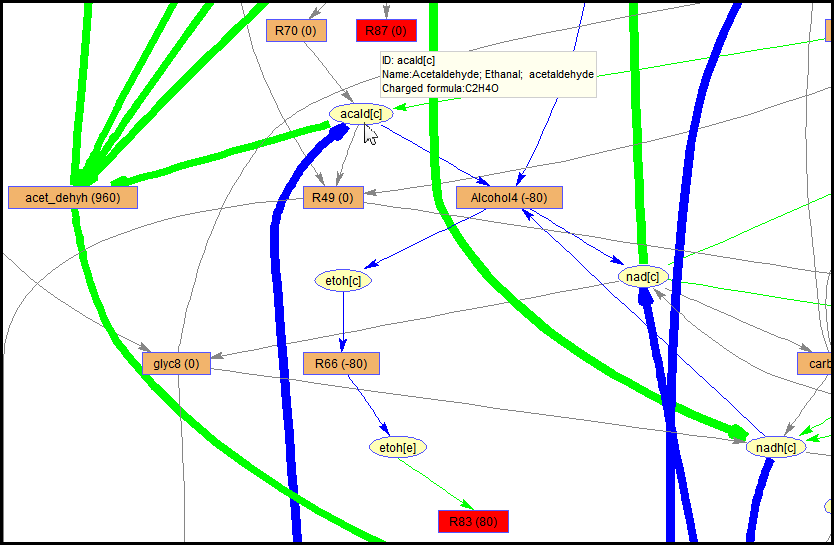

**Fig. 1 **Zoomed fragment of a large model. Reaction nodes (rectangle) contain IDs and flux rates. Metabolite nodes (ellipse) are marked by IDs. Forward and reverse fluxes (arrows) are green and blue correspondingly, zero fluxes are grey. The thickness of an arrow is proportional to the rate of flux. Rectangles of blocked and exchange reactions are marked by red. One node at a time can be chosen by a cursor to see detailed information: (1) ID, name, synonyms and equation for a reaction and (2) ID, name, synonyms and charged formula for a metabolite.  Metabolite *acald[c]*is selected by cursor for displaying of detailed information.  Creation of this figure is described in the “Anticipated results” section, Step 8.

Detailed information about any reaction and metabolite can be requested right on the visualization choosing the node of interest by cursor. To facilitate the analysis the Paint4Net creates a list of involved metabolites and a list of the dead end metabolites (metabolite cannot be produced or consumed caused by gap – missing reaction – in the model) (Thiele and Palsson, 2010) in the visualized part of the reaction network. That is a convenient feature analyzing larger visualizations where it becomes hard to be sure that a particular metabolite is or is not involved just by search of the abbreviation in the picture. The dead end metabolites are detected according to the S matrix (Palsson, 2006) of the biochemical model and the rates of reactions at steady state according to FBA. Flux rates below 10E−9 mmol g−1 h−1 are considered to be zero flux rates. To reduce the density of visualization a metabolite filter can be used. Stoichiometric model may have some particular metabolites (H, H2O, ATP, ADP, NAD, NADPH, NADP etc.), which are more involved in the metabolism, than other ones. It leads to a very tight interconnectivity and makes it harder to visualize larger models. For this reason both functions of the Paint4Net have special argument for the list of excludable metabolites. Each excluded metabolite reduces the number of interconnecting curves in the visualization of the model. Debugging of a model can be facilitated in several ways. The visualization shows the interconnections between reactions and metabolites and isolated parts of a network appear very clearly. There are three reasons why isolated reactions can be present in the model: (1) human made mistakes in the model while generating the model, (2) intentionally left gaps in case of no interest in specific metabolic process or (3) knowledge gaps in case of missing biochemical knowledge for the organism. Isolated parts can be related to metabolic dead-ends in the model (Thiele and Palsson, 2010). The Paint4Net is able to find the dead end metabolites and represent them in the visualization (red ellipses). Blocked reactions which cannot carry the fluxes (Thiele and Palsson, 2010) can appear in the model as intentionally blocked reactions (gene knockouts, flux constraints set to 0), however often there are cases when the model is stoichiometrically unbalanced or lower and upper bounds are set incorrectly. The Paint4Net can deal with this problem as well by showing the nodes of the blocked reactions in the visualization by red rectangles. The true power of visualization reflects when the user has to find Type III-extreme pathways (Thiele and Palsson, 2010) in the model. Those are stoichiometrically balanced cycles which can have fluxes even when all the substrate sources are cut down. According to FBA data the Paint4Net visualizes the network and then it is relatively easy to distinguish cycles by nonzero fluxes marked by green and blue arrows, which in most cases are caused by insufficient constraints of the flux and/or directionality. 

Paint4Net has been used in the development of stoichiometric models of Zymomonas mobilis (Pentjuss et al., 2013), Methanococcus maripaludis (Richards et al., 2016) and Kluyveromyces marxianus (Pentjuss et al., 2017). Paint4Net was used for to develop draft model, to identify network reactions connecting missing outputs to inputs and/or to produce figures for the published manuscript (Aurich and Thiele, 2012), (Demidenko et al., 2017), (Contador et al., 2015). It is used also for analysis and published figures in other studies (Koussa et al., 2014). Paint4Net is mentioned also as valuable supplement to other COBRA Tollboxes like ORCA (Mao and Verwoerd, 2014). Paint4Net has been used also for analysis of networks during building of modeling software (Rove et al., 2012) and supporting software tools (Rubina and Stalidzans, 2013), (Meitalovs and Stalidzans, 2013). Paint4Net is also used in a number of doctoral theses in different countries.

## MATERIALS

No materials are needed as Paint4Net is a software product.

## EQUIPMENT

The equipment has to be able to run MATLAB. 

## EQUIPMENT SETUP

The COBRA toolbox and the Bioinformatics toolbox are required to use the Paint4Net.

## PROCEDURE

The Paint4Net v1.3 contains two main commands for the visualization purposes:

- *[involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux)*;

- *[directionRxns, involvedMets, deadEnds] = draw_by_met(model,** metAbbr**, drawMap, radius, direction, excludeMets, flux)*.

## *Application of command* ***draw_by_rxn ***

***draw_by_rxn ***can be performed using **option** **A** in case COBRA model optimization results have to be visualized or **option** **B** if the interconnections between metabolites in COBRA file have to be visualized (See Fig. 2).

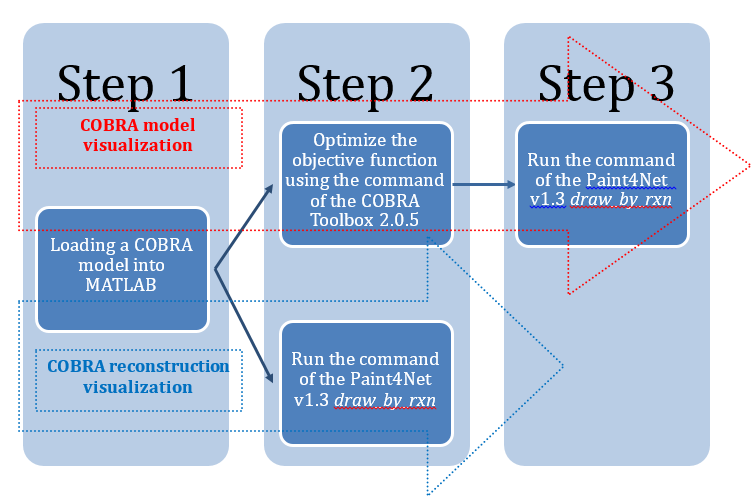

**Fig. 2.** The scenarios of an application of the command *draw_by_rxn*.

Before starting the tutorial, initialize the Cobra Toolbox if necessary and set a LP solver

initCobraToolbox(false) %don't update the toolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2026
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.50.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


changeCobraSolver ('gurobi', 'all', 1);

Could not find installation of matlab, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
removing: /Users/rui/Documents/MATLAB/cobratoolbox/src/analysis/thermo/componentContribution/new
removing: /Users/rui/Documents/MATLAB/cobratoolbox/src/analysis/thermo/groupContribution/new
removing: /Users/rui/Documents/MATLAB/cobratoolbox/src/analysis/thermo/inchi/new
removing: /Users/rui/Documents/MATLAB/cobratoolbox/src/analysis/thermo/molFiles/new
removing: /Users/rui/Documents/MATLAB/cobratoolbox/src/analysis/thermo/protons/new
removing: /Users/rui/Documents/MATLAB/cobratoolbox/src/analysis/thermo/trainingModel/new

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSol

%changeCobraSolver ('glpk', 'all', 1);

## *A****.**** COBRA model visualization* 

**i.** a COBRA model has to be loaded into MATLAB. The sample model is available at [http://www.biosystems.lv/files/Paint4Net%20sample%20pack%2008.07.2017.zip](http://www.biosystems.lv/files/Paint4Net%20sample%20pack%2008.07.2017.zip). Download the file and extract it in a folder of your choice. You can also use your own model.

model = xls2model('test_model.xls')